# Figure: Second one in discussion

We illustrate the ext excitation box in two coordinate

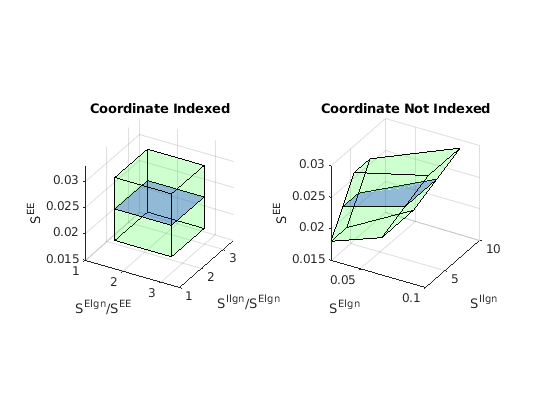

figure('Name','Fig7')
subplot 121
hold on
IndCord = [0 0 0; 
           0 1 0; 
           1 1 0; 
           1 0 0; 
           0 0 1; 
           0 1 1; 
           1 1 1; 
           1 0 1; % These 8 are cube vertices
           0 0 0.5; 
           0 1 0.5; 
           1 1 0.5; % These 4 are Fig2 box coordinate
           1 0 0.5] .* repmat([1.5,1.5,0.012],12,1) + repmat([1.5,1.5,0.018],12,1);
Boxfaces = [1 2 3 4; 2 6 7 3; 4 3 7 8; 1 5 8 4; 1 2 6 5; 5 6 7 8];
Fig2Face = [9 10 11 12];
patch('Vertices', IndCord, 'Faces', Boxfaces, 'FaceColor', 'g','FaceAlpha',0.1);
patch('Vertices', IndCord, 'Faces', Fig2Face, 'FaceColor', 'b','FaceAlpha',0.3);
view([30 30])
xlabel('S^{Elgn}/S^{EE}');
ylabel('S^{Ilgn}/S^{Elgn}');
zlabel('S^{EE}');
axis([1 3.5 1 3.5 0.015 0.033]); axis square
grid on
title('Coordinate Indexed')

subplot 122
hold on
NOIndCord = zeros(size(IndCord));
NOIndCord(:,3) = IndCord(:,3);
NOIndCord(:,1) = IndCord(:,1).*IndCord(:,3);
NOIndCord(:,2) = IndCord(:,2).*IndCord(:,1);
Boxfaces = [1 2 3 4; 2 6 7 3; 4 3 7 8; 1 5 8 4; 1 2 6 5; 5 6 7 8];
Fig2Face = [9 10 11 12];
patch('Vertices', NOIndCord, 'Faces', Boxfaces, 'FaceColor', 'g','FaceAlpha',0.1);
patch('Vertices', NOIndCord, 'Faces', Fig2Face, 'FaceColor', 'b','FaceAlpha',0.3);
view([30 30])
xlabel('S^{Elgn}');
ylabel('S^{Ilgn}');
zlabel('S^{EE}');
axis square
%axis([1 3.5 1 3.5 0.015 0.033]); 
grid on
title('Coordinate Not Indexed')